# Recursive Least Squares Based Trigonometric Fourier Series

Written By: Rasit Evduzen,06-Apr-2024

## RLSE Based Fourier Series Decomposition

Write an introduction here

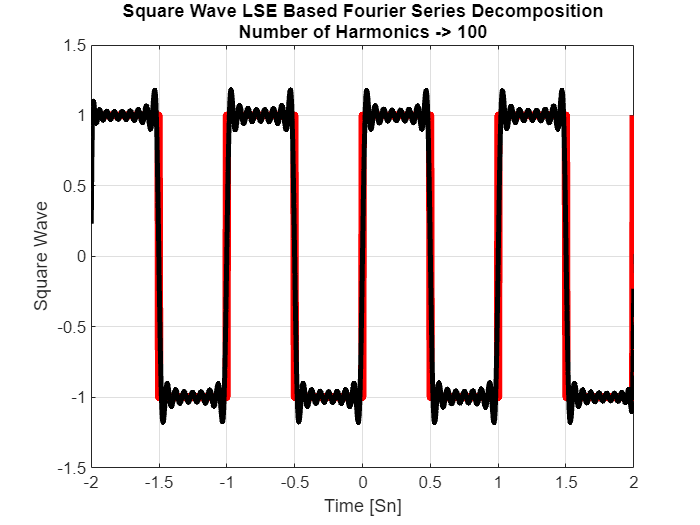

NoH = 100; % Number of Harmonics
produceAnimation(NoH)

function produceAnimation(NoH)
TimeVec = linspace(-2,2,1e3)';
SignalSquareWave = square(TimeVec*2*pi);

A = zeros(numel(TimeVec),NoH);
b = SignalSquareWave;
for k=1:NoH
    A(:,k) = sin(TimeVec*k);
end

% Create LS and RLSE Model
model_oder = NoH;
xRlse = .1*rand(model_oder,1);  % Random start RLSE state vector
P = 1e2 * eye(model_oder,model_oder);

%figure('units','normalized','outerposition',[0 0 1 1],'color','w')
for i = 1:size(SignalSquareWave,1)

    [xRlse,K,P] = rlse_online(A(i,:),b(i),xRlse,P);
    FSsignalSquareWave = 0;
    for j=1:NoH
        FSsignalSquareWave = [FSsignalSquareWave +  xRlse(j)*sin(TimeVec*j)];
    end

    % Plot Result
    if mod(i,1e1) == 0
        clf
        plot(TimeVec,SignalSquareWave,'r',LineWidth=5)
        hold on
        grid
        plot(TimeVec,FSsignalSquareWave,'k',LineWidth=3)
        title(["Square Wave LSE Based Fourier Series Decomposition", "Number of Harmonics -> "+num2str(NoH)])
        xlabel("Time [Sn]"),ylabel("Square Wave"),axis([min(TimeVec) max(TimeVec) -1.5 1.5])
        drawnow
    end
end
end

function [x,K,P] = rlse_online(a_k,b_k,x,P)
% One step of RLSE (Recursive Least Squares Estimation) algorithm
a_k = a_k(:);
b_k = b_k(:);
K = (P*a_k)/(a_k'*P*a_k+1); % Compute Gain K (Like Kalman Gain!)
x = x + K*(b_k-a_k'*x);     % State Update
P = P - K*a_k'*P;           % Covariance Update
end
